# Lab 9 3D deconvolution of the microscopy fluorescence image

LI Zhiying 12210309

## Introduction

    在现代细胞生物学领域，大多数三维荧光显微图像通常通过共聚焦显微镜获取。相比传统荧光显微镜，共聚焦显微镜由于其设计能够减少非焦平面荧光物体产生的雾状干扰，因此具有更高的成像质量。然而，尽管共聚焦显微镜有许多优点，其也存在一些限制。一个显著的缺点是获取共聚焦图像所需的激发光强度较高。这对于需要多焦平面成像的固定样本，或者需要多种染料标记的样本而言，可能会成为一个问题，因为为了获得满意的三维图像所需的激发光剂量可能会导致荧光染料的光漂白。

    为了解决这一问题，反卷积技术被提出，用于消除非焦平面荧光信号对图像质量的影响。早期的大部分反卷积算法基于已知的成像系统响应，即点扩散函数（Point Spread Function, PSF），该函数可以通过测量或估计获得。其中最经典的方法是线性逆滤波算法，该方法在空间域中对PSF的反卷积操作等价于傅里叶域中的除法。此外，维纳滤波（Wiener Filtering）、线性最小二乘法和Tikhonov滤波等其他线性方法也被广泛应用。为了进一步提升反卷积性能，后续提出了一些非线性迭代方法，例如Janson-Van Cittert算法、非线性最小二乘法和受约束的Tikhonov-Miller算法。

    在本次实验中，将学习使用不同的反卷积技术包括逆滤波、维纳滤波和最大似然估计（Richardson-Lucy迭代）算法，并在MATLAB中实现。通过对模拟数据和真实数据的分析，使用这三种方法进行图像处理，并通过对比处理结果分析三种算法的性能。

## Objectives

    1. 学习逆滤波和维纳滤波的原理，掌握其MATLAB的算法实现算法。

    2. 对比并分析不同方法所得结果的差异，深入理解各方法的优劣。

    3. 学习最大似然估计（R-L迭代）算法的实现过程。

## Principles

### 逆滤波（Inverse Filtering）

    逆滤波是一种直接的反卷积方法，其目标是通过已知的点扩散函数 (PSF) 来恢复模糊图像。成像过程中，由于光学系统的限制，图像会因卷积效应失真。逆滤波通过假设图像退化模型已知，试图直接反向消除这种模糊。其原理是利用模糊图像和PSF之间的数学关系，将模糊效果反向“解除”。图像退化模型可以表示为：

   
$$g\left(x,y\right)=h\left(x,y\right)\ast f\left(x,y\right)+n\left(x,y\right)$$


其中，g(x,y)是观测到的模糊图像，f(x,y)是原始图像，h(x,y)是点扩散函数，n(x,y)是噪声。通过傅里叶变换，卷积操作可转化为频域的乘积关系：


$$G\left(u,v\right)=H\left(u,v\right)\cdot F\left(u,v\right)+N\left(u,v\right)$$


在噪声可以忽略的情况下，通过频域除法估计原始图像的频域：


$$F\left(u,v\right)=\frac{G\left(u,v\right)}{H\left(u,v\right)}$$


然后通过逆傅里叶变换得到复原的图像。

    逆滤波的优点是方法简单，但其对噪声非常敏感。如果 H(u,v)在某些频率接近零，噪声会被显著放大，导致结果失真。因此，它适合于噪声较低的场景。

### 维纳滤波 (Wiener Filtering)

    维纳滤波是一种改进的图像复原方法，其目标是在保留图像细节的同时减少噪声干扰。与逆滤波直接消除模糊不同，维纳滤波通过结合噪声统计特性优化图像复原过程。维纳滤波的公式为：


$$F\left(u,v\right)=\frac{H*\left(u,v\right)}{{|H\left(u,v\right)|}^2 +\frac{S_n \left(u,v\right)}{S_f \left(u,v\right)}}\cdot G\left(u,v\right)$$


其中：$H*\left(u,v\right)$ 是 $H\left(u,v\right)$ 的复共轭, $S_n \left(u,v\right)$是噪声的功率谱密度，$S_f \left(u,v\right)$是原始图像的功率谱密度；$\frac{S_n \left(u,v\right)}{S_f \left(u,v\right)}$表示噪声与信号功率谱的比值。

    维纳滤波根据信噪比自适应地调整滤波器的行为。当信号功率高于噪声时，滤波器更倾向于保留图像细节；当噪声占主导时，滤波器会加强对噪声的抑制。相比于逆滤波，维纳滤波更稳健，适用于包含中等或高噪声的场景。

### R-L迭代 (Richardson-Lucy Iteration)

    R-L迭代是一种基于统计理论的非线性图像复原算法，主要用于处理高噪声图像和保留复杂细节的应用场景。它假设成像过程中符合泊松分布，迭代公式为：


$$f_{k+1} \left(x,y\right)=f_k \left(x,y\right)\cdot \left\lbrack \frac{g\left(x,y\right)}{\left(h*f_k \right)\left(x,y\right)}*h^* \left(-x,-y\right)\right\rbrack$$


其中：$f_k \left(x,y\right)$是第k次迭代的图像估计，$g\left(x,y\right)$是观测图像，$h\left(-x,-y\right)$和$h^* \left(-x,-y\right)$分别是点扩散函数及其逆向卷积。

    R-L迭代通过逐步调整图像估计值来减少模糊和噪声。每次迭代都会计算当前估计值与观测图像的差异，并据此进行校正，从而逐步逼近真实图像。与线性方法相比，R-L迭代能够更好地恢复细节信息，特别是在高噪声环境下。然而，由于其需要多次迭代，计算量较大，并且容易受到初始估计值的影响。

## Task 1

利用计算出的模糊微球数据生成噪声干扰数据；

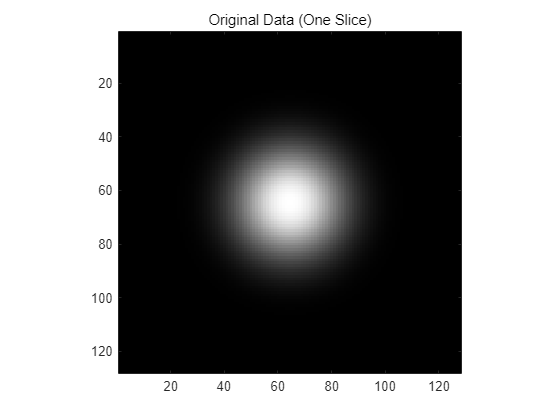

clear; clc;
data = load('simblurNoNoise.mat');
blur_data = data.blur;
figure;
imagesc(blur_data(:,:,100));
axis image; colormap('gray');
title('Original Data (One Slice)');

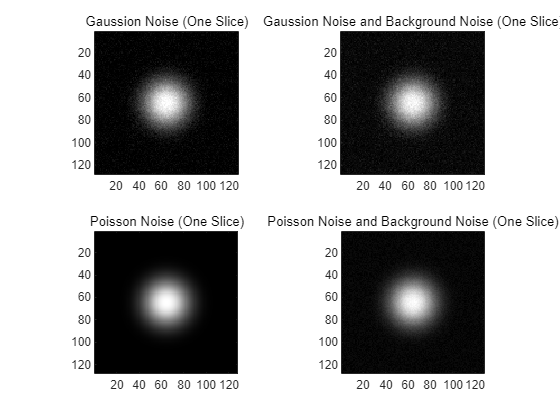

[m,n,p] = size(blur_data);
blur_data = blur_data / max(blur_data(:));

data_with_gaussion_noise = zeros(m,n,p);
data_with_poisson_noise = zeros(m,n,p);
data_with_gaussion_noise_and_background = zeros(m,n,p);
data_with_poisson_noise_and_background = zeros(m,n,p);

for i = 1:p
    img = blur_data(:,:,i);
    img = img / max(img,[],"all");
    gaussian_noise_level = 0.001;
    gaussian_noise_img = imnoise(img, 'gaussian', 0, gaussian_noise_level);
    poisson_noise_img = imnoise(img, 'poisson');
    background_noise = 0.05 * rand(m, n); 
    gaussian_with_background = gaussian_noise_img + background_noise;
    poisson_with_background = poisson_noise_img + background_noise;

    % gaussian_noise_img = min(gaussian_noise_img, 1);
    % poisson_noise_img = min(poisson_noise_img, 1);
    % gaussian_with_background = min(gaussian_with_background, 1);
    % poisson_with_background = min(poisson_with_background, 1);
    
    data_with_gaussion_noise(:, :, i) = gaussian_noise_img;
    data_with_poisson_noise(:, :, i) = poisson_noise_img;
    data_with_gaussion_noise_and_background(:, :, i) = gaussian_with_background;
    data_with_poisson_noise_and_background(:, :, i) = poisson_with_background;
end

figure;
subplot(2,2,1);
imagesc(data_with_gaussion_noise(:,:,100));
axis image; colormap('gray');
title('Gaussion Noise (One Slice)');
subplot(2,2,2);
imagesc(data_with_gaussion_noise_and_background(:,:,100));
axis image; colormap('gray');
title('Gaussion Noise and Background Noise (One Slice)');
subplot(2,2,3);
imagesc(data_with_poisson_noise(:,:,100));
axis image; colormap('gray');
title('Poisson Noise (One Slice)');
subplot(2,2,4);
imagesc(data_with_poisson_noise_and_background(:,:,100));
axis image; colormap('gray');
title('Poisson Noise and Background Noise (One Slice)');

***Result: ***

        1. 计算得到的初始微球数据经过归一化处理，确保所有像素的荧光强度均不超过 1，以满足真实物理条件下的荧光强度分布。在归一化后的数据上，分别加入了高斯噪声（均值为 0，标准差适中）和泊松噪声，以模拟真实显微系统中成像过程的典型噪声源。

        2. 加入高斯噪声后，图像中像素值出现一定程度的波动，特别是在微球边界区域，噪声引入的模糊效应较为明显。泊松噪声在模拟低光子数探测情况下的统计波动较为有效，图像中不同区域的随机性增强，但总体上仍保持微球的形状特征。添加背景噪声后，整个图像呈现更加接近真实显微成像的效果，其中高光区域（微球部分）和低光区域（背景）之间的对比度降低。

***Discussion:***

        1. 初始微球荧光强度设定为 1，归一化过程有效避免了像素值超出物理范围的问题，同时确保图像数据适用于后续的噪声模拟与去噪算法。

        2. 加入高斯噪声后，微球图像的边界变得模糊，尤其是微弱信号部分噪声影响更为显著。这与真实系统中低信噪比区域的表现一致。泊松噪声主要影响微球区域的亮度波动，使高光区域的像素值随机分布，这种现象在低光子成像系统中较为常见。

## Task 2

实现逆滤波和维纳滤波方法。

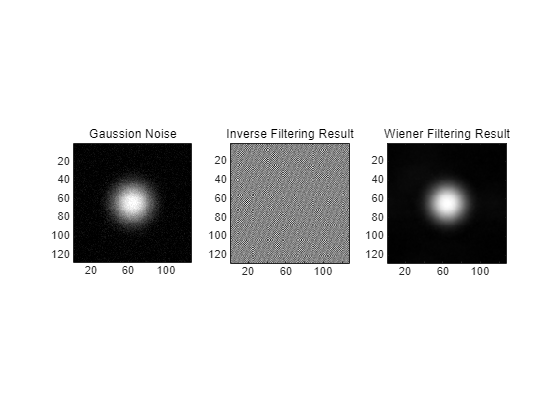

load('PSFG&Lsmall.mat');
PSF = PSFsmall;

H = psf2otf(PSF, size(data_with_gaussion_noise));
G = fftn(data_with_gaussion_noise);

% ------------ 逆滤波方法 ------------
H_abs = abs(H); 
H_inv = conj(H) ./ (H_abs.^2 + eps); 
F_inv = H_inv .* G; 
reconstructed_image_inv_gaussion = real(ifftn(F_inv));

% ------------ 维纳滤波方法 ------------
K = 9e3; 
Wiener_filter = conj(H) ./ (H_abs.^2 + K); 
F_wiener = Wiener_filter .* G; 
reconstructed_image_wiener_gaussion = real(ifftn(F_wiener)); 

figure;
subplot(1,3,1);
imagesc(data_with_gaussion_noise(:,:,100));
axis image; colormap('gray');
title('Gaussion Noise');
subplot(1,3,2);
imagesc(reconstructed_image_inv_gaussion(:,:,100));
axis image; colormap('gray');
title('Inverse Filtering Result');
subplot(1,3,3);
imagesc(reconstructed_image_wiener_gaussion(:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result');

***Result:***

        我们使用加入高斯噪声的模拟数据为例，实现了逆滤波和微纳滤波。

        1. 使用逆滤波方法恢复的图像对高频噪声的抑制能力较弱，表现为较多的噪声残留。使用逆滤波难以恢复结构特征。

        2. 维纳滤波方法在恢复图像时显著减少了噪声影响，表现为更清晰的边界和较好的信号还原。

***Discussion：***

        1. 逆滤波仅依赖点扩散函数（PSF）的逆特性，对噪声不具备抑制能力，因此恢复图像中噪声成分较多。在频域中，PSF 值接近零的位置可能引入数值不稳定性，进一步加剧了噪声的影响。

        2. 维纳滤波通过引入噪声信号比（NSR，或参数 K）进行优化，能够在信号还原和噪声抑制之间实现平衡。参数 K 的选择直接影响滤波效果。当前设定的 K=9e3 有效抑制了噪声，同时保留了微球结构的主要细节。

## Task 3

实现R-L迭代算法

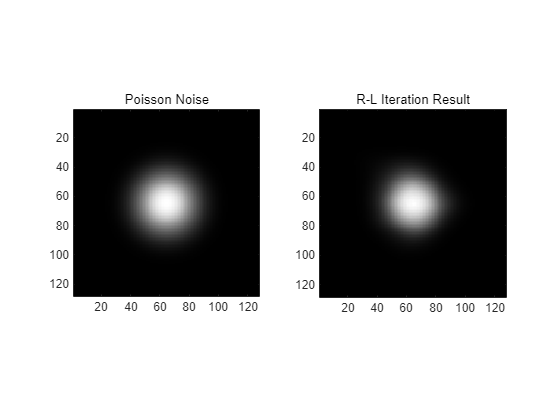

max_iterations = 10; 
epsilon = 1e-8; 

H = psf2otf(PSF, size(data_with_poisson_noise));
H_conj = conj(H);
reconstructed_image = ones(size(data_with_poisson_noise));

for iter = 1:max_iterations

    G_estimated = ifftn(fftn(reconstructed_image) .* H); 

    ratio = data_with_poisson_noise ./ (G_estimated + epsilon);

    correction = ifftn(fftn(ratio) .* H_conj);
    reconstructed_image = reconstructed_image .* real(correction);
end

figure;
subplot(1, 2, 1);
imagesc(data_with_poisson_noise(:,:,100));
axis image; colormap('gray');
title('Poisson Noise');
subplot(1, 2, 2); 
imagesc(reconstructed_image(:,:,100));
axis image; colormap('gray');
title('R-L Iteration Result');

***Result:***

        我们使用引入了泊松噪声的数据进行R-L迭代的实现，最大迭代次数设为10。

        经过10次迭代后，图像中噪声的影响被显著抑制，微球的形状和边界得到了较好的恢复。图像细节有所增强，尤其是在高信号区域，泊松噪声的影响被有效减少。

***Discussion：***

         R-L 算法是一种基于最大似然估计的反卷积方法，特别适合处理泊松噪声污染的图像数据。通过逐次迭代，算法可以有效地重构图像的细节和结构信息，同时对噪声具有一定的抑制能力。

## Task 4

对模拟数据进行逆滤波、维纳滤波和R-L迭代，并对结果进行比较；

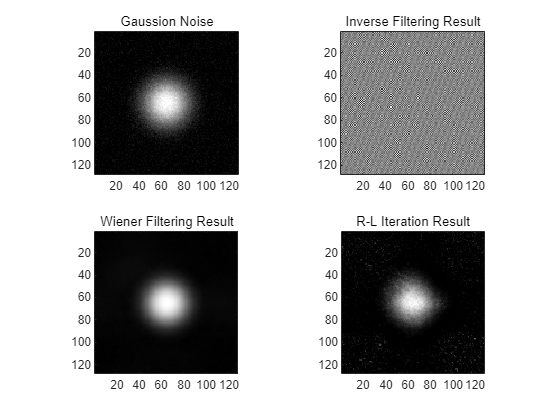

% Gaussion Noise
reconstructed_image_RL_gaussion = deconvlucy(data_with_gaussion_noise,PSF,10);
figure;
subplot(2,2,1);
imagesc(data_with_gaussion_noise(:,:,100));
axis image; colormap('gray');
title('Gaussion Noise');
subplot(2,2,2);
imagesc(reconstructed_image_inv_gaussion(:,:,100));
axis image; colormap('gray');
title('Inverse Filtering Result');
subplot(2,2,3);
imagesc(reconstructed_image_wiener_gaussion(:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result');
subplot(2,2,4);
imagesc(reconstructed_image_RL_gaussion(:,:,100));
axis image; colormap('gray');
title('R-L Iteration Result');

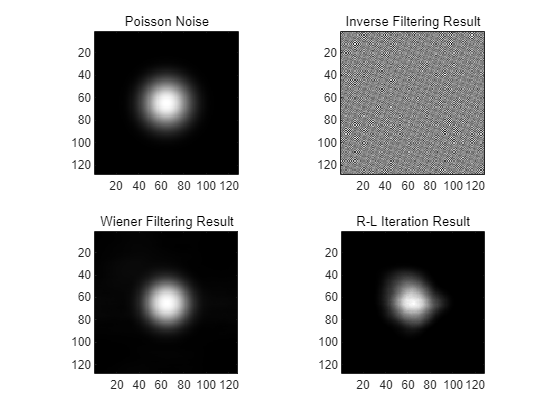

% Poisson Noise
H = psf2otf(PSF, size(data_with_poisson_noise));
G = fftn(data_with_poisson_noise);

% ------------ 逆滤波方法 ------------
H_abs = abs(H); 
H_inv = conj(H) ./ (H_abs.^2 + eps); 
F_inv = H_inv .* G; 
reconstructed_image_inv_poisson = real(ifftn(F_inv));

% ------------ 维纳滤波方法 ------------
K = 9e3; 
Wiener_filter = conj(H) ./ (H_abs.^2 + K); 
F_wiener = Wiener_filter .* G; 
reconstructed_image_wiener_poisson = real(ifftn(F_wiener)); 

reconstructed_image_RL_poisson = deconvlucy(data_with_poisson_noise,PSF,10);
figure;
subplot(2,2,1);
imagesc(data_with_poisson_noise(:,:,100));
axis image; colormap('gray');
title('Poisson Noise');
subplot(2,2,2);
imagesc(reconstructed_image_inv_poisson(:,:,100));
axis image; colormap('gray');
title('Inverse Filtering Result');
subplot(2,2,3);
imagesc(reconstructed_image_wiener_poisson(:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result');
subplot(2,2,4);
imagesc(reconstructed_image_RL_poisson(:,:,100));
axis image; colormap('gray');
title('R-L Iteration Result');

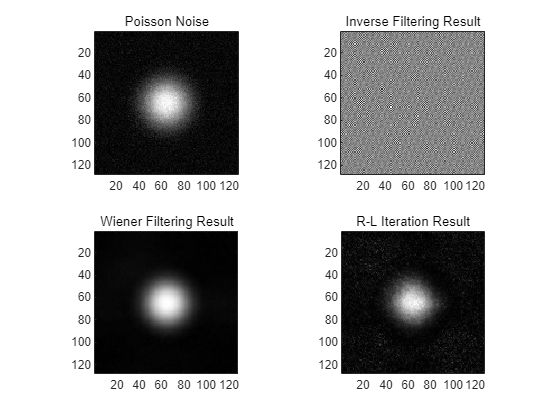


% Gaussion Noise + Background Noise 
H = psf2otf(PSF, size(data_with_gaussion_noise_and_background));
G = fftn(data_with_gaussion_noise_and_background);

% ------------ 逆滤波方法 ------------
H_abs = abs(H); 
H_inv = conj(H) ./ (H_abs.^2 + eps); 
F_inv = H_inv .* G; 
reconstructed_image_inv_gaussion_and_background = real(ifftn(F_inv));

% ------------ 维纳滤波方法 ------------
K = 9e3; 
Wiener_filter = conj(H) ./ (H_abs.^2 + K); 
F_wiener = Wiener_filter .* G; 
reconstructed_image_wiener_gaussion_and_background = real(ifftn(F_wiener)); 

reconstructed_image_RL_gaussion_and_background = deconvlucy(data_with_gaussion_noise_and_background,PSF,10);
figure;
subplot(2,2,1);
imagesc(data_with_gaussion_noise_and_background(:,:,100));
axis image; colormap('gray');
title('Poisson Noise');
subplot(2,2,2);
imagesc(reconstructed_image_inv_gaussion_and_background(:,:,100));
axis image; colormap('gray');
title('Inverse Filtering Result');
subplot(2,2,3);
imagesc(reconstructed_image_wiener_gaussion_and_background(:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result');
subplot(2,2,4);
imagesc(reconstructed_image_RL_gaussion_and_background(:,:,100));
axis image; colormap('gray');
title('R-L Iteration Result');

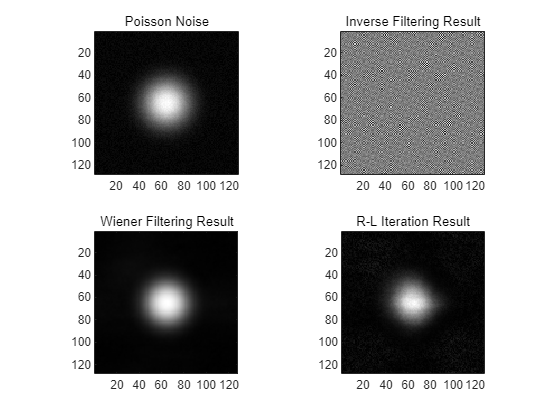


% Poisson Noise + Background Noise 
H = psf2otf(PSF, size(data_with_poisson_noise_and_background));
G = fftn(data_with_poisson_noise_and_background);

% ------------ 逆滤波方法 ------------
H_abs = abs(H); 
H_inv = conj(H) ./ (H_abs.^2 + eps); 
F_inv = H_inv .* G; 
reconstructed_image_inv_poisson_noise_and_background = real(ifftn(F_inv));

% ------------ 维纳滤波方法 ------------
K = 9e3; 
Wiener_filter = conj(H) ./ (H_abs.^2 + K); 
F_wiener = Wiener_filter .* G; 
reconstructed_image_wiener_poisson_noise_and_background= real(ifftn(F_wiener)); 

reconstructed_image_RL_poisson_noise_and_background = deconvlucy(data_with_poisson_noise_and_background,PSF,10);
figure;
subplot(2,2,1);
imagesc(data_with_poisson_noise_and_background(:,:,100));
axis image; colormap('gray');
title('Poisson Noise');
subplot(2,2,2);
imagesc(reconstructed_image_inv_poisson_noise_and_background(:,:,100));
axis image; colormap('gray');
title('Inverse Filtering Result');
subplot(2,2,3);
imagesc(reconstructed_image_wiener_poisson_noise_and_background(:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result');
subplot(2,2,4);
imagesc(reconstructed_image_RL_poisson_noise_and_background(:,:,100));
axis image; colormap('gray');
title('R-L Iteration Result');

Result：

        1. 对所有噪声场景，逆滤波恢复原始图像结构和噪声抑制能力效果都很差。

        2. 维纳滤波通过调整参数 KKK 提高了噪声抑制能力，恢复的图像信噪比显著优于逆滤波。对高斯噪声和噪声加背景的处理效果尤为明显，细节复原较好。

        3. R-L 方法在多次迭代后，图像的细节和边界得到了恢复，噪声抑制效果显著。

Disussion：

        1. 逆滤波方法对噪声不具备鲁棒性，适用于噪声较低的图像复原场景。但在噪声占主导时，该方法容易放大高频噪声，导致复原质量下降。

        2. 维纳滤波通过引入噪声功率比 (KKK) 实现了信号与噪声的平衡，对随机噪声的抑制能力较强。其优势在于参数可调，适应性强。

        3.  R-L 方法在处理泊松噪声时效果最佳，能够在多次迭代中逐步恢复图像细节，但需注意迭代次数的设置，以避免过拟合和伪影生成。

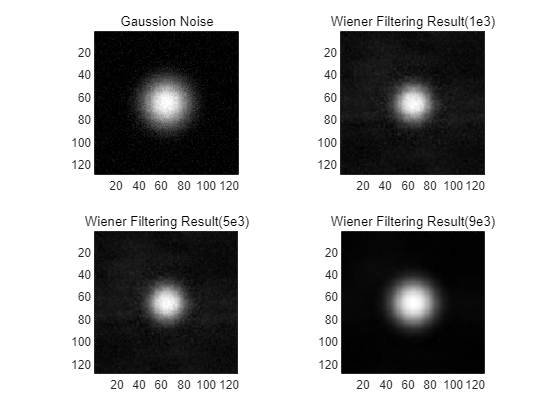

% Change NSR
H = psf2otf(PSF, size(data_with_gaussion_noise));
G = fftn(data_with_gaussion_noise);

K = 1e3;
Wiener_filter = conj(H) ./ (H_abs.^2 + K); 
F_wiener = Wiener_filter .* G; 
reconstructed_image_wiener_gaussion_1e3 = real(ifftn(F_wiener)); 

k = 5e3;
Wiener_filter = conj(H) ./ (H_abs.^2 + K); 
F_wiener = Wiener_filter .* G; 
reconstructed_image_wiener_gaussion_5e3 = real(ifftn(F_wiener)); 

figure;
subplot(2,2,1);
imagesc(data_with_gaussion_noise(:,:,100));
axis image; colormap('gray');
title('Gaussion Noise');
subplot(2,2,2);
imagesc(reconstructed_image_wiener_gaussion_1e3(:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result(1e3)');
subplot(2,2,3);
imagesc(reconstructed_image_wiener_gaussion_5e3 (:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result(5e3)');
subplot(2,2,4);
imagesc(reconstructed_image_wiener_gaussion(:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result(9e3)');

***Result: ***

        1. K = 1e3: 噪声抑制效果较好，细节部分基本得到了保留。由于 K 值较小，维纳滤波倾向于更多地保留原始信号，但可能会导致少量噪声残留。

        2. K = 5e3: 相较于 K=1e3，噪声的抑制更为明显，图像更为平滑，但一些细节开始丢失。

        3. K = 9e3: 进一步增大 K 后，噪声几乎完全被抑制，但复原图像变得过于平滑，部分边缘和细节明显丢失。

***Discussion:   ***

        维纳滤波的性能高度依赖 K 的选择。较小的 K 值可以更好地恢复信号细节，但可能导致噪声残留。较大的 K 值能够更好地抑制噪声，但可能导致图像细节的过度平滑。适中的 K 值能在噪声抑制和细节保留之间达到较好的平衡。

## Task 5

对真实数据进行逆滤波、维纳滤波和R-L迭代处理，并对结果进行比较；

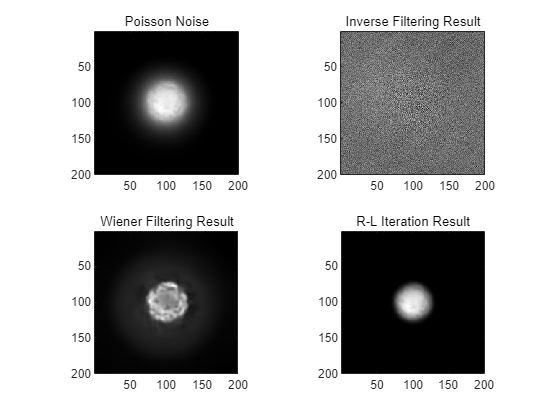

clear; clc;
load('realdat.mat');
load('PSFreal.mat');
blur_data = blur;
PSF = PSFsmall;

H = psf2otf(PSF, size(blur_data));
G = fftn(blur_data);

% ------------ 逆滤波方法 ------------
H_abs = abs(H); 
H_inv = conj(H) ./ (H_abs.^2 + eps); 
F_inv = H_inv .* G; 
reconstructed_image_inv_real = real(ifftn(F_inv));

% ------------ 维纳滤波方法 ------------
K = 9e3; 
Wiener_filter = conj(H) ./ (H_abs.^2 + K); 
F_wiener = Wiener_filter .* G; 
reconstructed_image_wiener_real= real(ifftn(F_wiener)); 

reconstructed_image_RL_real = deconvlucy(blur_data,PSF,10);

figure;
subplot(2,2,1);
imagesc(blur_data(:,:,100));
axis image; colormap('gray');
title('Poisson Noise');
subplot(2,2,2);
imagesc(reconstructed_image_inv_real(:,:,100));
axis image; colormap('gray');
title('Inverse Filtering Result');
subplot(2,2,3);
imagesc(reconstructed_image_wiener_real(:,:,100));
axis image; colormap('gray');
title('Wiener Filtering Result');
subplot(2,2,4);
imagesc(reconstructed_image_RL_real(:,:,100));
axis image; colormap('gray');
title('R-L Iteration Result');

***Result：***

        对于真实数据我们使用三种方法进行重建。从结果中我们可以看到R-L迭代的效果最好，其次是微纳滤波，逆滤波效果最差。

***Discussion：***

        逆滤波因其简单且不适应噪声环境，复原效果最差；

        维纳滤波在快速复原中表现良好，但细节保留能力有限；

        R-L 迭代表现最佳，能够在噪声抑制和细节恢复之间取得良好平衡。